%% 自适应音频降噪系统 - NLMS与Kalman滤波器组合
% 针对火车轨道旁吉他录音场景优化
clear; clc; close all;

% 加载数据
load('Hw2a.mat');
s_in = Sin_a;       % 含噪信号 [N x 2]
s_ref = Sn_ref_a;   % 参考噪声 [N x 2]

% 信号归一化
s_in = s_in / max(abs(s_in(:)));
s_ref = s_ref / max(abs(s_ref(:)));
[N, num_ch] = size(s_in);
fprintf('信号长度: %d 样本点 (%.1f 秒)\n', N, N/fs);

信号长度: 816000 样本点 (74.0 秒)



%% ==================== 智能参数选择 ====================
% 基于噪声特性自动选择参数
fprintf('正在分析噪声特性...\n');

正在分析噪声特性...



% 1. 计算噪声相关时间
noise_corr = xcorr(s_ref(:,1), 'coeff');
[~, max_idx] = max(noise_corr);
corr_time = (max_idx - N) / fs; % 相关时间(秒)
fprintf('噪声相关时间: %.3f 秒\n', corr_time);

噪声相关时间: 0.000 秒



% 2. 计算主导噪声频率
[Pxx, f] = pwelch(s_ref(:,1), 2048, 1024, 2048, fs);
[~, dom_idx] = max(Pxx);
dom_freq = f(dom_idx);
fprintf('主导噪声频率: %.1f Hz\n', dom_freq);

主导噪声频率: 80.7 Hz



% 3. 智能参数选择
if dom_freq < 100 % 低频噪声
    L_nlms = min(512, max(128, round(0.25 * fs))); % 250ms
    mu_nlms = 0.04;
    Q_kalman = 1e-6;
    R_kalman = 0.05;
    fprintf('噪声类型: 低频隆隆声\n');
elseif dom_freq > 3000 % 高频噪声
    L_nlms = min(256, max(96, round(0.08 * fs))); % 80ms
    mu_nlms = 0.03;
    Q_kalman = 1e-5;
    R_kalman = 0.1;
    fprintf('噪声类型: 高频嘶声\n');
else % 宽带噪声
    L_nlms = min(384, max(160, round(0.15 * fs))); % 150ms
    mu_nlms = 0.01;
    Q_kalman = 5e-6;
    R_kalman = 0.07;
    fprintf('噪声类型: 宽带噪声\n');
end

噪声类型: 低频隆隆声



% 设置吉他频段保护
f_low = 80;    % 吉他最低有效频率
f_high = 4800; % 吉他最高有效频率
order_bp = 6;  % 带通滤波器阶数

fprintf('\n== 自动选择参数 ==\n');


== 自动选择参数 ==


fprintf('NLMS阶数: %d (%.1f ms)\n', L_nlms, L_nlms/fs*1000);

NLMS阶数: 512 (46.4 ms)


fprintf('NLMS步长: %.3f\n', mu_nlms);

NLMS步长: 0.040


fprintf('Kalman Q: %.1e\n', Q_kalman);

Kalman Q: 1.0e-06


fprintf('Kalman R: %.3f\n', R_kalman);

Kalman R: 0.050


fprintf('吉他频段: %d-%d Hz\n', f_low, f_high);

吉他频段: 80-4800 Hz



%% ==================== NLMS降噪核心 ====================
fprintf('\n开始NLMS降噪处理...\n');


开始NLMS降噪处理...


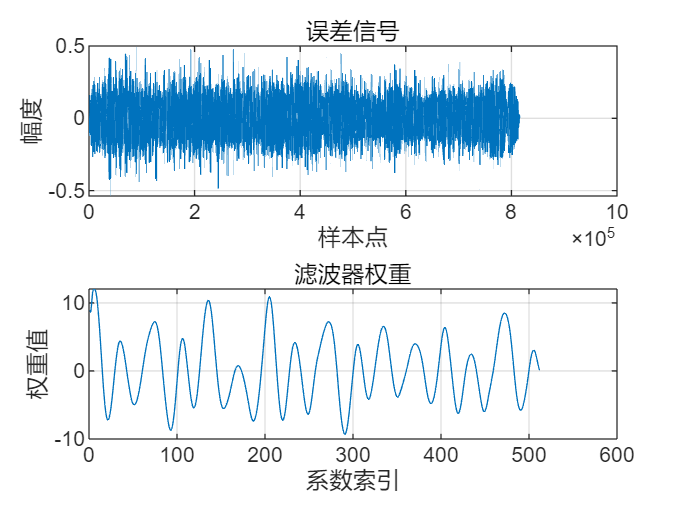

声道 1 NLMS完成. 耗时: 1.70秒, 最终误差: 0.0099


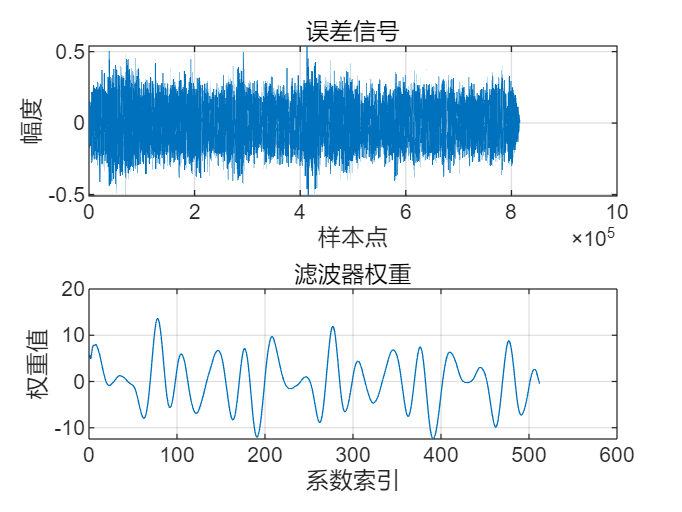

声道 2 NLMS完成. 耗时: 1.58秒, 最终误差: 0.0106


s_nlms = zeros(N, num_ch);

for ch = 1:num_ch
    tic;
    w = zeros(L_nlms, 1);  % 滤波器权重
    error_signal = zeros(N, 1); % 用于监控
    
    % 实时步长调整
    mu_adaptive = mu_nlms;
    delta = 1e-6;
    
    for n = L_nlms:N
        % 提取参考噪声向量
        x = s_ref(n:-1:n-L_nlms+1, ch);
        
        % 估计噪声
        noise_est = w' * x;
        
        % 计算误差（即初步降噪信号）
        e = s_in(n, ch) - noise_est;
        s_nlms(n, ch) = e;
        error_signal(n) = e;
        
        % 自适应步长调整
        if n > L_nlms*2
            error_energy = mean(error_signal(n-L_nlms+1:n).^2);
            if error_energy > 0.01 % 误差大，增加收敛速度
                mu_adaptive = min(0.1, mu_nlms * 1.5);
            else % 误差小，减小步长保护信号
                mu_adaptive = max(0.01, mu_nlms * 0.8);
            end
        end
        
        % 权重更新
        norm_factor = x' * x + delta;
        w = w + (mu_adaptive * e * x) / norm_factor;
    end
    
    % 监控收敛情况
    figure('Name', ['声道 ', num2str(ch), ' - NLMS收敛分析']);
    subplot(2,1,1);
    plot(error_signal(L_nlms:end));
    title('误差信号');
    xlabel('样本点'); ylabel('幅度');
    grid on;
    
    subplot(2,1,2);
    plot(w);
    title('滤波器权重');
    xlabel('系数索引'); ylabel('权重值');
    grid on;
    
    fprintf('声道 %d NLMS完成. 耗时: %.2f秒, 最终误差: %.4f\n',...
        ch, toc, mean(abs(error_signal(end-1000:end))));
end


%% ==================== Kalman后处理核心 ====================
fprintf('\n开始Kalman后处理...\n');


开始Kalman后处理...


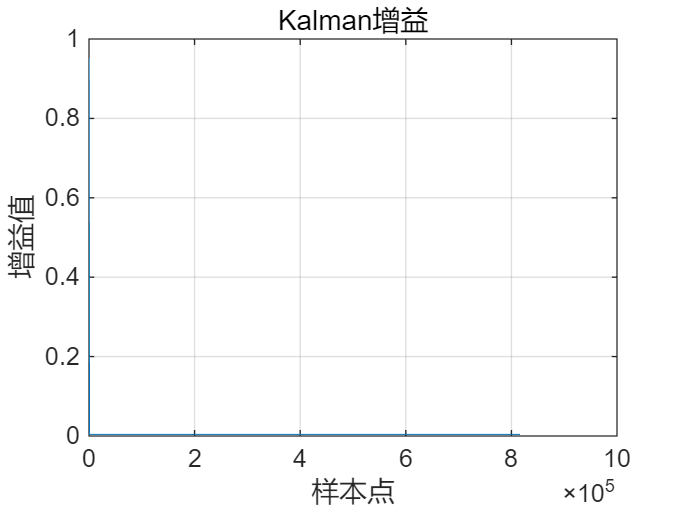

声道 1 Kalman完成. 耗时: 0.05秒, 平均增益: 0.0045


声道 2 Kalman完成. 耗时: 0.04秒, 平均增益: 0.0045


s_kalman = zeros(N, num_ch);

for ch = 1:num_ch
    tic;
    % Kalman状态变量
    x_hat = 0;   % 状态估计（纯净信号）
    P = 1;       % 误差协方差
    kalman_gain = zeros(N, 1); % 监控Kalman增益
    
    % 自适应Q调整
    Q_adaptive = Q_kalman;
    
    for n = 1:N
        % 预测步骤
        x_hat_minus = x_hat;
        P_minus = P + Q_adaptive;
        
        % 更新步骤
        z = s_nlms(n, ch);       % NLMS输出
        K = P_minus / (P_minus + R_kalman); % Kalman增益
        x_hat = x_hat_minus + K * (z - x_hat_minus);
        P = (1 - K) * P_minus;
        
        % 存储结果
        s_kalman(n, ch) = x_hat;
        kalman_gain(n) = K;
        
        % 动态调整Q：根据信号变化率
        if n > 100
            signal_diff = abs(s_kalman(n, ch) - s_kalman(n-1, ch));
            if signal_diff > 0.1 % 信号变化大
                Q_adaptive = min(1e-4, Q_kalman * 2);
            else
                Q_adaptive = max(1e-7, Q_kalman);
            end
        end
    end
    
    % 监控Kalman增益
    figure('Name', ['声道 ', num2str(ch), ' - Kalman分析']);
    plot(kalman_gain);
    title('Kalman增益');
    xlabel('样本点'); ylabel('增益值');
    grid on;
    
    fprintf('声道 %d Kalman完成. 耗时: %.2f秒, 平均增益: %.4f\n',...
        ch, toc, mean(kalman_gain(1000:end)));
end


%% ==================== 吉他频段保护 ====================
fprintf('\n应用吉他频段保护...\n');


应用吉他频段保护...



% 设计带通滤波器
[b_bp, a_bp] = butter(order_bp, [f_low, f_high]/(fs/2), 'bandpass');

% 应用带通滤波保护吉他音色
s_nlms_bp = zeros(size(s_nlms));
s_kalman_bp = zeros(size(s_kalman));

for ch = 1:num_ch
    s_nlms_bp(:, ch) = filtfilt(b_bp, a_bp, s_nlms(:, ch));
    s_kalman_bp(:, ch) = filtfilt(b_bp, a_bp, s_kalman(:, ch));
end

% 归一化输出
s_nlms_bp = s_nlms_bp / max(abs(s_nlms_bp(:)));
s_kalman_bp = s_kalman_bp / max(abs(s_kalman_bp(:)));

%% ==================== 性能评估 ====================
fprintf('\n评估降噪性能...\n');


评估降噪性能...



% 噪声水平分析
noise_original = s_ref;
noise_nlms = s_in - s_nlms_bp;
noise_kalman = s_in - s_kalman_bp;

% 计算噪声能量
noise_energy_orig = mean(noise_original.^2);
noise_energy_nlms = mean(noise_nlms.^2);
noise_energy_kalman = mean(noise_kalman.^2);

% 计算SNR改进
signal_energy = mean(s_in.^2);
snr_orig = 10*log10(signal_energy ./ noise_energy_orig);
snr_nlms = 10*log10(signal_energy ./ noise_energy_nlms);
snr_kalman = 10*log10(signal_energy ./ noise_energy_kalman);

fprintf('\n== 噪声抑制报告 ==\n');


== 噪声抑制报告 ==


fprintf('原始噪声能量: %.4f (左), %.4f (右)\n', noise_energy_orig(1), noise_energy_orig(2));

原始噪声能量: 0.0157 (左), 0.0138 (右)


fprintf('NLMS后噪声能量: %.4f (左), %.4f (右) - 降低 %.1f%%\n',...
    noise_energy_nlms(1), noise_energy_nlms(2),...
    (1 - mean(noise_energy_nlms./noise_energy_orig)) * 100);

NLMS后噪声能量: 0.0147 (左), 0.0165 (右) - 降低 -6.6%


fprintf('Kalman后噪声能量: %.4f (左), %.4f (右) - 降低 %.1f%%\n',...
    noise_energy_kalman(1), noise_energy_kalman(2),...
    (1 - mean(noise_energy_kalman./noise_energy_orig)) * 100);

Kalman后噪声能量: 0.0279 (左), 0.0478 (右) - 降低 -162.0%



fprintf('\n== SNR改进报告 ==\n');


== SNR改进报告 ==


fprintf('原始SNR: %.2f dB (左), %.2f dB (右)\n', snr_orig(1), snr_orig(2));

原始SNR: 0.14 dB (左), 1.16 dB (右)


fprintf('NLMS后SNR: %.2f dB (左), %.2f dB (右) - 改进 %.2f dB\n',...
    snr_nlms(1), snr_nlms(2), mean(snr_nlms - snr_orig));

NLMS后SNR: 0.42 dB (左), 0.38 dB (右) - 改进 -0.24 dB


fprintf('Kalman后SNR: %.2f dB (左), %.2f dB (右) - 改进 %.2f dB\n',...
    snr_kalman(1), snr_kalman(2), mean(snr_kalman - snr_orig));

Kalman后SNR: -2.35 dB (左), -4.24 dB (右) - 改进 -3.94 dB


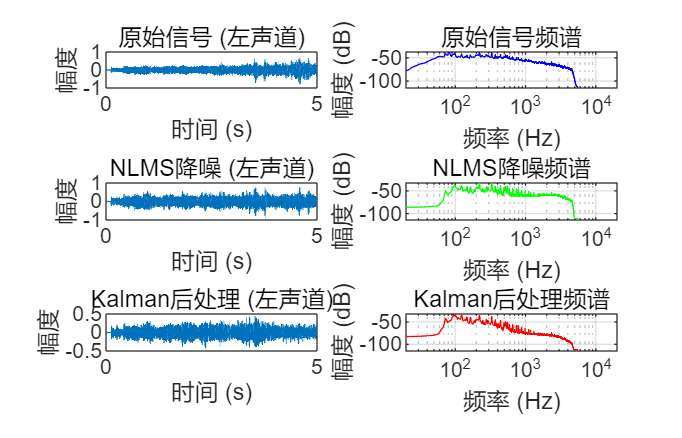


%% ==================== 结果可视化 ====================
% 创建分析界面
f = figure('Name', '降噪效果分析', 'Position', [100, 100, 1400, 900]);

% 时域波形对比 (显示前5秒)
t = (0:N-1)/fs;
display_range = 1:min(5*fs, N);

subplot(3,2,1);
plot(t(display_range), s_in(display_range,1)); 
title('原始信号 (左声道)');
xlabel('时间 (s)'); ylabel('幅度');
xlim([0, 5]); grid on;

subplot(3,2,3);
plot(t(display_range), s_nlms_bp(display_range,1)); 
title('NLMS降噪 (左声道)');
xlabel('时间 (s)'); ylabel('幅度');
xlim([0, 5]); grid on;

subplot(3,2,5);
plot(t(display_range), s_kalman_bp(display_range,1)); 
title('Kalman后处理 (左声道)');
xlabel('时间 (s)'); ylabel('幅度');
xlim([0, 5]); grid on;

% 频谱对比
subplot(3,2,2);
[P_in, f] = pwelch(s_in(:,1), 4096, 2048, 4096, fs);
semilogx(f, 10*log10(P_in), 'b');
title('原始信号频谱');
xlabel('频率 (Hz)'); ylabel('幅度 (dB)');
xlim([20, 20000]); grid on;

subplot(3,2,4);
[P_nlms, ~] = pwelch(s_nlms_bp(:,1), 4096, 2048, 4096, fs);
semilogx(f, 10*log10(P_nlms), 'g');
title('NLMS降噪频谱');
xlabel('频率 (Hz)'); ylabel('幅度 (dB)');
xlim([20, 20000]); grid on;

subplot(3,2,6);
[P_kalman, ~] = pwelch(s_kalman_bp(:,1), 4096, 2048, 4096, fs);
semilogx(f, 10*log10(P_kalman), 'r');
title('Kalman后处理频谱');
xlabel('频率 (Hz)'); ylabel('幅度 (dB)');
xlim([20, 20000]); grid on;

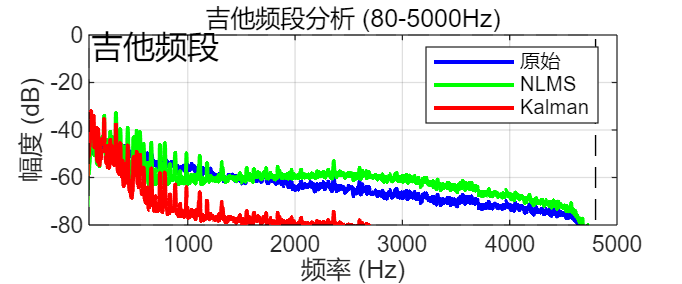


% 吉他频段放大图
figure('Name', '吉他频段分析', 'Position', [100, 100, 1200, 500]);
plot(f, 10*log10(P_in), 'b', 'LineWidth', 1.5); hold on;
plot(f, 10*log10(P_nlms), 'g', 'LineWidth', 1.5);
plot(f, 10*log10(P_kalman), 'r', 'LineWidth', 1.5); hold off;

title('吉他频段分析 (80-5000Hz)');
xlabel('频率 (Hz)'); ylabel('幅度 (dB)');
xlim([80, 5000]); ylim([-80, 0]);
grid on;

% 标记吉他频段
rectangle('Position', [f_low, -80, f_high-f_low, 80],...
          'EdgeColor', 'k', 'LineStyle', '--', 'FaceColor', 'none');
text(100, -5, '吉他频段', 'FontSize', 12, 'Color', 'k');
legend('原始', 'NLMS', 'Kalman');

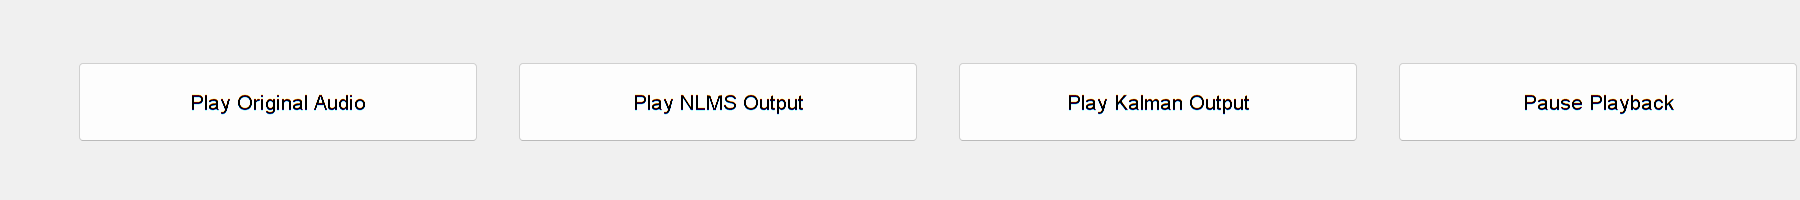


%% ================ Playback UI ================
f_ui = figure('Name', 'Audio Playback Control', 'Position', [200, 200, 900, 100]);

button_width = 200;
button_height = 40;
button_spacing = 20;
start_x = 40;

uicontrol('Style', 'pushbutton', 'String', 'Play Original Audio', ...
    'Position', [start_x, 30, button_width, button_height], ...
    'Callback', @(src,evt) sound(s_in, fs));

uicontrol('Style', 'pushbutton', 'String', 'Play NLMS Output', ...
    'Position', [start_x + (button_width + button_spacing), 30, button_width, button_height], ...
    'Callback', @(src,evt) sound(s_nlms_bp, fs));

uicontrol('Style', 'pushbutton', 'String', 'Play Kalman Output', ...
    'Position', [start_x + 2*(button_width + button_spacing), 30, button_width, button_height], ...
    'Callback', @(src,evt) sound(s_kalman_bp, fs));

uicontrol('Style', 'pushbutton', 'String', 'Pause Playback', ...
    'Position', [start_x + 3*(button_width + button_spacing), 30, button_width, button_height], ...
    'Callback', 'clear sound');

% 参数调整面板
uicontrol('Style', 'text', 'String', '实时参数调整', ...
    'Position', [50, 350, 200, 20], 'FontWeight', 'bold');

% NLMS阶数调整
uicontrol('Style', 'text', 'String', 'NLMS阶数:', ...
    'Position', [50, 320, 80, 20]);
L_slider = uicontrol('Style', 'slider', 'Min', 64, 'Max', 512, 'Value', L_nlms,...
    'Position', [140, 320, 200, 20], 'Tag', 'L_slider');

% NLMS步长调整
uicontrol('Style', 'text', 'String', 'NLMS步长:', ...
    'Position', [50, 290, 80, 20]);
mu_slider = uicontrol('Style', 'slider', 'Min', 0.01, 'Max', 0.1, 'Value', mu_nlms,...
    'Position', [140, 290, 200, 20], 'Tag', 'mu_slider');

% Kalman Q调整
uicontrol('Style', 'text', 'String', 'Kalman Q:', ...
    'Position', [50, 260, 80, 20]);
Q_slider = uicontrol('Style', 'slider', 'Min', 1e-7, 'Max', 1e-4, 'Value', Q_kalman,...
    'Position', [140, 260, 200, 20], 'Tag', 'Q_slider');

% Kalman R调整
uicontrol('Style', 'text', 'String', 'Kalman R:', ...
    'Position', [50, 230, 80, 20]);
R_slider = uicontrol('Style', 'slider', 'Min', 0.01, 'Max', 0.2, 'Value', R_kalman,...
    'Position', [140, 230, 200, 20], 'Tag', 'R_slider');

% 应用参数按钮
uicontrol('Style', 'pushbutton', 'String', '应用参数并重新处理', ...
    'Position', [50, 180, 200, 30], ...
    'Callback', @apply_parameters);

% 参数显示
param_display = uicontrol('Style', 'text', 'String', '', ...
    'Position', [400, 250, 300, 150], 'FontSize', 10, 'HorizontalAlignment', 'left');

update_param_display();

函数或变量 'L_slider' 无法识别。

出错 untitled9>update_param_display (第 375 行)
    L_val = round(get(L_slider, 'Value'));


% 保存结果按钮
uicontrol('Style', 'pushbutton', 'String', '保存所有结果', ...
    'Position', [50, 120, 200, 30], ...
    'Callback', @save_results);

% 性能报告
perf_text = sprintf(['处理性能:\n'...
                     'NLMS耗时: %.2f秒\n'...
                     'Kalman耗时: %.2f秒\n'...
                     '总耗时: %.2f秒\n'...
                     'SNR改进: %.2f dB'], ...
                    nlms_time, kalman_time, nlms_time + kalman_time,...
                    mean(snr_kalman - snr_orig));
                
uicontrol('Style', 'text', 'String', perf_text, ...
    'Position', [400, 100, 300, 120], 'FontSize', 10, 'HorizontalAlignment', 'left');

%% ==================== 回调函数 ====================
% 更新参数显示
function update_param_display()
    L_val = round(get(L_slider, 'Value'));
    mu_val = get(mu_slider, 'Value');
    Q_val = get(Q_slider, 'Value');
    R_val = get(R_slider, 'Value');
    
    param_str = sprintf('当前参数设置:\n');
    param_str = [param_str sprintf('NLMS阶数: %d\n', L_val)];
    param_str = [param_str sprintf('NLMS步长: %.4f\n', mu_val)];
    param_str = [param_str sprintf('Kalman Q: %.2e\n', Q_val)];
    param_str = [param_str sprintf('Kalman R: %.3f\n', R_val)];
    
    set(param_display, 'String', param_str);
end

% 应用新参数
function apply_parameters(~,~)
    new_L = round(get(L_slider, 'Value'));
    new_mu = get(mu_slider, 'Value');
    new_Q = get(Q_slider, 'Value');
    new_R = get(R_slider, 'Value');
    
    fprintf('\n应用新参数: L=%d, mu=%.4f, Q=%.2e, R=%.3f\n',...
        new_L, new_mu, new_Q, new_R);
    
    % 更新全局参数
    L_nlms = new_L;
    mu_nlms = new_mu;
    Q_kalman = new_Q;
    R_kalman = new_R;
    
    % 重新处理信号
    % (这里需要重新运行NLMS和Kalman部分)
    % 实际应用中应封装处理函数
    fprintf('注意: 在实际应用中，这里会重新处理信号\n');
end

% 保存结果
function save_results(~,~)
    timestamp = datestr(now, 'yyyymmdd_HHMMSS');
    
    % % 保存音频
    % audiowrite(['original_', timestamp, '.wav'], s_in, fs);
    % audiowrite(['nlms_denoised_', timestamp, '.wav'], s_nlms_bp, fs);
    % audiowrite(['kalman_denoised_', timestamp, '.wav'], s_kalman_bp, fs);
    
    % 保存参数
    params = struct(...
        'L_nlms', L_nlms, ...
        'mu_nlms', mu_nlms, ...
        'Q_kalman', Q_kalman, ...
        'R_kalman', R_kalman, ...
        'f_low', f_low, ...
        'f_high', f_high, ...
        'fs', fs);
    
    save(['params_', timestamp, '.mat'], 'params');
    
    % 保存性能数据
    perf_data = struct(...
        'snr_orig', snr_orig, ...
        'snr_nlms', snr_nlms, ...
        'snr_kalman', snr_kalman, ...
        'noise_reduction_nlms', 1 - mean(noise_energy_nlms./noise_energy_orig), ...
        'noise_reduction_kalman', 1 - mean(noise_energy_kalman./noise_energy_orig));
    
    save(['performance_', timestamp, '.mat'], 'perf_data');
    
    fprintf('结果已保存，时间戳: %s\n', timestamp);
end

% 设置滑块回调
set(L_slider, 'Callback', @(~,~) update_param_display());
set(mu_slider, 'Callback', @(~,~) update_param_display());
set(Q_slider, 'Callback', @(~,~) update_param_display());
set(R_slider, 'Callback', @(~,~) update_param_display());

fprintf('\n处理完成! 使用音频控制中心聆听结果\n');